# Kondition des Ausgleichsproblems

Für $\delta>0$ betrachten wir folgendes Ausgleichsproblem 

     
$$ A=\pmatrix{ 1 & 0 \cr 0 & 1 \cr 0 & 0}, 
\quad 
b= \pmatrix{ 1 \cr 1 \cr \delta}, \quad \|Ax-b\|_2 \to \min.
$$


Beim gestörten Problem wählen wir dieselbe Matrix $A$, aber einen gestörten  Datenvektor $\tilde b = b +\Delta b$ mit Störung

       $\Delta b= 10^{-1} \pmatrix{ 1 \cr -1 \cr 0}$.

Es gilt $\frac{\|\Delta b\|_2}{\|b\|_2}=10^{-1}\left(\frac{2}{2+\delta}\right)^\frac12$.

# Aktivität:

Wählen Sie  einen $\delta$-Wert, $\delta \geq 1$, z.B. $\delta=10^{k}$, $k=0,1,\ldots$ 

delta= 10^2

delta = 100

Wählen Sie die Art der Visualisierung: visualize $=1$(ohne Störung) oder visualize $=2$ (mit Störung)

global visualize;
visualize=1;
fprintf('\n Beachten Sie die Skalierungen der Achsen in der Grafik \n')


 Beachten Sie die Skalierungen der Achsen in der Grafik 


Jetzt wird das Lineare Ausgleichsproblem gelöst:

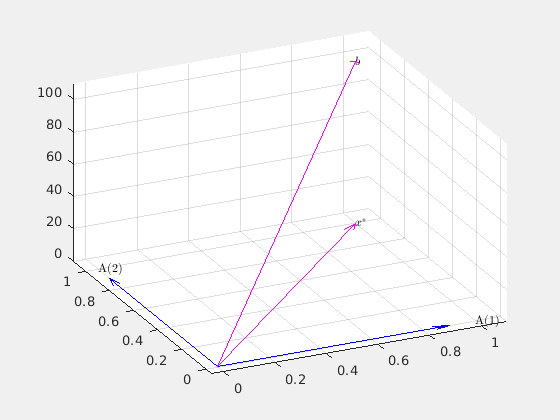

 [kappa,theta,relerr_x] = loesung(delta);

Die Kondition der Matrix ist:

fprintf('\n Konditionszahl der Matrix ist %4.2f.\n',kappa)


 Konditionszahl der Matrix ist 1.00.


Der Cosinus des Winkels zwischen $b$ und ${\rm Bild}(A)$ ist:

fprintf('\n Kosinus des Winkels ist %6.2e.\n',cos(theta))


 Kosinus des Winkels ist 1.41e-02.


Die Kondition des linearen Ausgleichsproblems beträgt:

fprintf('\n Konditionzahl des linearen Ausgleichsproblems ist %6.2e.\n',kappa/cos(theta))


 Konditionzahl des linearen Ausgleichsproblems ist 7.07e+01.


Die relativen Fehler in $b$ und $x$ sind:

disp('---------------------')

---------------------


fprintf('\n Relative Fehler in b und x sind:\n')


 Relative Fehler in b und x sind:


relerr_b= norm([0.1; -0.1;0])/norm([1;1;delta])

relerr_b = 0.0014

relerr_x

relerr_x = 0.1000

# Aktivität:

Erklären Sie die beobachteten Verhältnisse zwischen Fehler im Datenvektor $b$ und Fehler im Ergebnis $x$.

function [kappa,theta,relerr_x] = loesung(delta)
global visualize;
clf
A=[1 0;0 1;0 0];
b=[1; 1; delta];
xast= A\b;
theta= acos(norm(A*xast)/norm(b));

db1= [0.1; -0.1 ;0 ];
btilde1= b+db1;
kappa= cond(A);
xtilde1= A\btilde1;
relerr_x= norm(xast - xtilde1)/norm(xast);

e1 = A(:,1)';
e2 = A(:,2)';
e3 = b';
e4 = btilde1';
e6 = [xast(1) xast(2) 0];
e7 = [xtilde1(1) xtilde1(2) 0];
e9 = -db1';

txt1 = 'A(1)';
txt2 = 'A(2)';
txt3 = '$b$';
txt4 = '$\tilde b$';
txt6 = '$x^\ast$';
txt7 = '$\tilde{x^\ast}$';
txt9 = '$\Delta b$';

starts = zeros(5,3);
ends = [e1; e2; e3; e4 ;  e6; e7;  e9; e1; [0 0 -0.1]];


rotate3d on;
grid on;

xmax = 2*max(ends(3:9,1));
ymax =0.5;
zmax =0.5;
vaxis=[-0.05 1.1 -0.05 1.1 0 1.1*delta];
hold off
axis(vaxis)
hold on;

% Plot A
qA=quiver3(starts(1:2,1), starts(1:2,2), starts(1:2,3), ends(1:2,1), ends(1:2,2), ends(1:2,3));
qA.Color='blue';
qA.LineWidth=0.1;
qA.Tag='A';
qA.AutoScale='on';
text( ends(1,1), ends(1,2), ends(1,3),txt1,'Interpreter','latex', ...
    'FontUnits','normalized','FontSize',0.035)
text( ends(2,1), ends(2,2), ends(2,3),txt2,'Interpreter','latex', ...
    'FontUnits','normalized','FontSize',0.035)

% Plot b and x
scaleHead= 0.2/delta;
q_bx= quiver3(starts(1:2,1), starts(1:2,2), starts(1:2,3), ends([3 5],1), ends([3 5],2), ends([3 5],3));
q_bx.Color='magenta';
q_bx.Tag='bx';
q_bx.AutoScale='off';
q_bx.MaxHeadSize=scaleHead;
text( ends(3,1), ends(3,2), ends(3,3),txt3,'Interpreter','latex', ...
    'FontUnits','normalized','FontSize',0.035)
text( ends(5,1), ends(5,2), ends(5,3),txt6,'Interpreter','latex', ...
    'FontUnits','normalized','FontSize',0.035)

if (visualize > 1)
    % Plot Delta b
    q_db= quiver3(ends(4,1), ends(4,2), ends(4,3), ends(7,1), ends(7,2), ends(7,3));
    q_db.Color='cyan';
    text( sum(ends(3:4,1))/2, sum(ends(3:4,2))/2, sum(ends(3:4,3))/2,txt9,'Interpreter','latex', ...
        'FontUnits','normalized','FontSize',0.035)
    
    % Plot Tilde B and Tilde x
    q_tilde_bx= quiver3(starts(1:2,1), starts(1:2,2), starts(1:2,3), ends([4 6],1), ends([4 6],2), ends([4 6],3));
    q_tilde_bx.Color='red';
    q_tilde_bx.AutoScale='off';
    q_tilde_bx.MaxHeadSize=scaleHead;
    text( ends(4,1), ends(4,2), ends(4,3),txt4,'Interpreter','latex', ...
        'FontUnits','normalized','FontSize',0.035)
    text( ends(6,1), ends(6,2), ends(6,3),txt7,'Interpreter','latex', ...
        'FontUnits','normalized','FontSize',0.035)
end


view(-25,35)
hold off;



end